# Simple Image Editor using Spacial Filtering

**Select an image file**

Enter the filename of the image to be used, including its file extension *(ex. img9.jpg)*.

filename = 'img9.jpg';
imageRaw = rgb2gray(sampleImage);
imageSize = size(imageRaw);

**Convert image to grayscale**

See converted grayscale image in comparison to the original image.

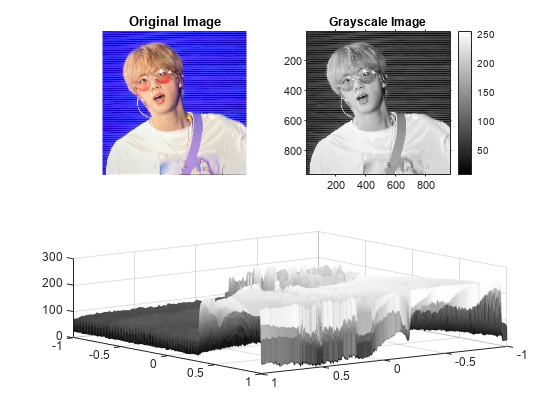

% Display images
colormap gray;
colorbar;
subplot(2,4,[1 2])
imshow(sampleImage)
title("Original Image")

subplot(2,4,[3 4])
imagesc(imageRaw)
colorbar;
axis square;
set(gca, 'TickDir', 'out');
title("Grayscale Image")

subplot(2,4,[5 8])
mesh(f1,f2,imageRaw);
%title('');
set(gca,'XDir','reverse','YDir','reverse');

[f1,f2] = freqspace(imageSize,'meshgrid'); 
% Note: freqspace was used because freqz2 is only limited to 64x64

**Prepare image data for spacial filtering using 2D Fast Fourier Transform (FFT)**

Compute the distance of each position from the center frequency.

r = sqrt(f1.^2 + f2.^2)

r =            1.4142135623731          1.41274119130544          1.41127035956183          1.40980107196015          1.40833333333333          1.40686714852935          1.40540252241128          1.40393945985731          1.40247796576076          1.40101804503011          1.39955970258904          1.39810294337641          1.39664777234634           1.3951941944682          1.39374221472664          1.39229183812159          1.39084306966834          1.38939591439749          1.38795037735504          1.38650646360236          1.38506417821622          1.38362352628885          1.38218451292792          1.38074714325655          1.37931142241337          1.37787735555253           1.3764449478437          1.37501420447208          1.37358513063847          1.37215773155923          1.37073201246633          1.36930797860736          1.36788563524555          1.36646498765976          1.36504604114456          1.36362880101017          1.36221327258253          1.36079946120327        

Get the 2D Fast Fourier Transform using **fft2** function.

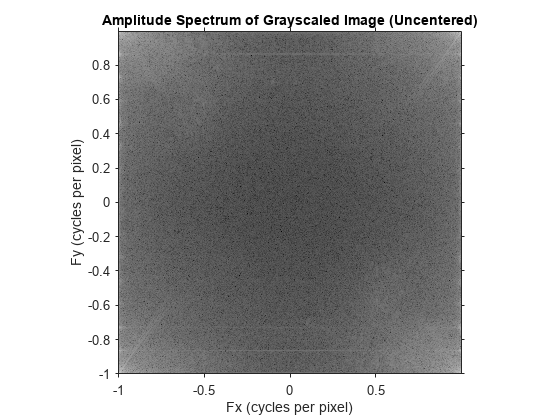

fftRaw = fft2(imageRaw);

% Tuning of data for visualization
temp = abs(fftRaw);
temp(temp<10^-10) = 10^-10; 
temp = log10(temp);

% Visualization
figure;
colormap gray;
imagesc(mean(f1),mean(f2,2),temp);
title('Amplitude Spectrum of Grayscaled Image (Uncentered)');
axis xy;
axis square;
set(gca, 'TickDir', 'out');
xlabel('Fx (cycles per pixel)');
ylabel('Fy (cycles per pixel)');

Shift the zero-frequency component to center of spectrum using **fftshift** function.

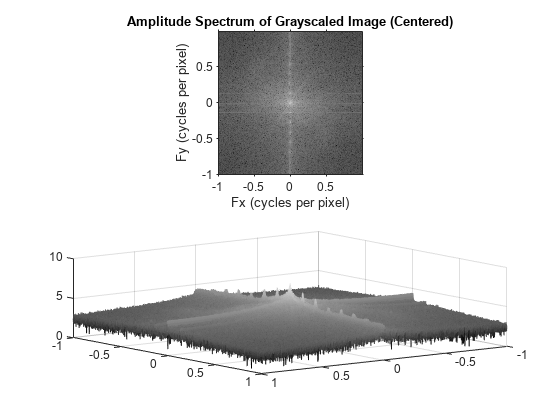

fftRaw = fftshift(fftRaw);

% Tuning of data for visualization
temp = abs(fftRaw);
temp(temp<10^-10) = 10^-10; 
temp = log10(temp);

% Visualization
figure;
colormap gray;
subplot(2,1,1)
imagesc(mean(f1),mean(f2,2),temp);
title('Amplitude Spectrum of Grayscaled Image (Centered)');
axis xy;
axis square;
set(gca, 'TickDir', 'out');
xlabel('Fx (cycles per pixel)');
ylabel('Fy (cycles per pixel)');
subplot(2,1,2)
mesh(f1,f2,temp);
%title('');
set(gca,'XDir','reverse','YDir','reverse')

**Design a filter template**

Create a matrix of ones with the same size as the image.

filt = ones(size(f1))

filt =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

**Select a filter type**

filterType = 'bandstop';
maxR = max(r,[],"all");
minR = min(r,[],"all");
midR1 = maxR/2;

**Set cut-off frequencies**

If **Lowpass** or **Highpass** **Filter** is selected, **cutoff1 **frequency will be its cut-off frequency. Otherwise, if **Bandpass** or **Bandstop Filter** is selected, **cutoff1** frequency will be the lower limit of the cut-off frequency range.

cutoff1 = 0.4;
midR2 = (maxR-cutoff1)/2;

If **Bandpass** or **Bandstop Filter** is selected, **cutoff2** frequency will be the upper limit of the cut-off frequency range. Otherwise, if **Lowpass** or **Highpass** **Filter** is selected, this value will be disregarded. 

cutoff2 = 0.98;

**Create the filter**

Based on the selected filter type, build the filter by setting the values outside of the desired cut-off frequency to zero. 

switch filterType
    case 'lowpass'
        filt(r>cutoff1) = 0
    case 'highpass'
        filt(r<cutoff1) = 0
    case 'bandpass'
        filt((r<cutoff2)|(r>cutoff1)) = 0
    case 'bandstop'
        filt((r>cutoff2)|(r<cutoff1)) = 0
end

filt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

**Apply spacial filtering **

Multiply the generated filter by the 2D Fast Fourier Transform of the grayscale image.

% Apply filter on image
filteredFFT = filt.*fftRaw

filteredFFT =                           0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     0i                          0 +                     

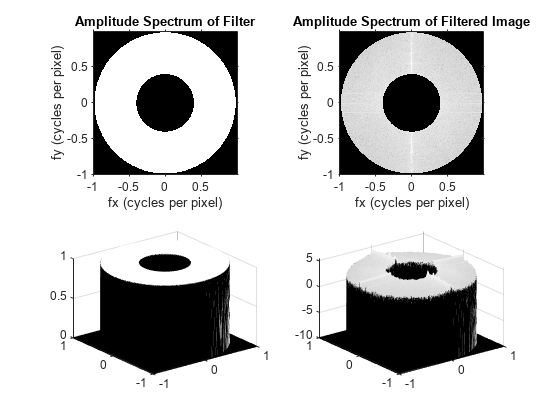

% Visualization
figure;
colormap gray;
subplot(2,2,1);
imagesc(mean(f1),mean(f2,2),abs(filt));
title('Amplitude Spectrum of Filter');
axis xy;
axis square;
set(gca, 'TickDir', 'out');
xlabel('fx (cycles per pixel)');
ylabel('fy (cycles per pixel)');

subplot(2,2,3);
mesh(f1,f2,filt);

temp = abs(filteredFFT);
temp(temp < 10^-10) = 10^-10; 
temp = log10(temp); 

subplot(2,2,2)
imagesc(mean(f1),mean(f2,2),temp);
title('Amplitude Spectrum of Filtered Image');
axis xy;
axis square;
set(gca, 'TickDir', 'out');
xlabel('fx (cycles per pixel)');
ylabel('fy (cycles per pixel)');

subplot(2,2,4)
mesh(f1,f2,temp);

**Reconstruct the image **

Rebuild the image from the filtered FFT using the **ifftshift** and **ifft2** functions. 

% Undo fftshift
filteredImage = ifftshift(filteredFFT); 
% Undo fft2
filteredImage = ifft2(filteredImage);
filteredFFT = abs(filteredFFT);

**Output**

Here is a full comparison of the images processed throughout. 

*Pick a colormap to see the grayscale images using different colormaps. Colormaps only vary the presentation of data, and does not alter the data.*

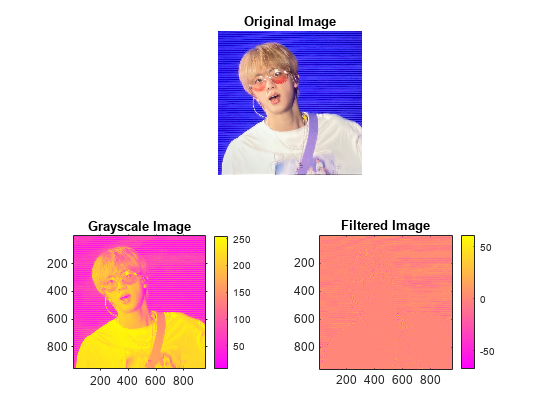

% Visualization
figure;

% Aesthetics
colormap spring;

subplot(2,2,[1 2])
imshow(sampleImage)
title("Original Image")

subplot(2,2,3)
imagesc(imageRaw)
colorbar;
axis square;
set(gca, 'TickDir', 'out');
title("Grayscale Image")

subplot(2,2,4)
imagesc(filteredImage);
title('Filtered Image');
colorbar;
axis square